# **Week 6-8: Examining Non-Linear Effects through the NLSE for QPSK**

The code below examines the non-linear effects in an optic fibre, in addition to attenuation and chromatic dispersion, through the solution of the non-linear Schrodinger equation using the split-step Fourier method

## **Transmitter**

The model of the transmitter consists of the following elements:

- A symbol generator which modulates source bits using BPSK and QPSK.

- An IQ modulator which modulates the output of a laser according to an electrical signal.

### Modulation

clear all; clearvars;

% Parameters
NSymb = 100000; % No. of symbols 
SpS = 2; % Samples per symbol
Rs = 50e9; % Symbol rate in symbols/sec
SNR_vals = [0:10];
laserPw_dBm = [30:45];
T = 1/(SpS*Rs); % Sampling period in s
t= [0:NSymb*SpS - 1]*T; % Time vector for plotting time-series data

voltageLevels = [-pi/16, pi/16]'; % Discrete voltage levels for BPSK and QPSK

% -------------------------------------------------------------------------------

% % FOR BPSK:
% % Generating random bit sequence(s)
% sourceBitsBPSK = randi([0 1], NSymb, length(laserPw_dBm)); % Matrix of source bits for BPSK
% sourceSymbolsBPSK = pskmod(sourceBitsBPSK, 2) % Maps source bit vector to symbol vector
% 
% % Modulating voltage with generated symbols
% vI_BPSK = ones(size(sourceSymbolsBPSK)); vQ_BPSK = zeros(size(sourceSymbolsBPSK));
% 
% vI_BPSK(real(sourceSymbolsBPSK)>=0) = voltageLevels(2); % Maps 1 -> pi/16
% vI_BPSK(real(sourceSymbolsBPSK)<0) = voltageLevels(1); % Maps -1 -> -pi/16
% 
% vI_BPSK_upsampled = repelem(vI_BPSK, SpS, 1); % Upsampling according to SpS
% vQ_BPSK_upsampled = repelem(vQ_BPSK, SpS, 1); % Upsampling according to SpS
% 
% % Visualising in-phase voltage
% stairs(t(1:10*SpS), vI_BPSK_upsampled(1:10*SpS,1), "o-");
% hold on
% stairs(t(1:10*SpS), vQ_BPSK_upsampled(1:10*SpS,1), "o-");
% title("Modulated Voltages for BPSK")
% xlabel("Time / s")
% ylabel("Voltage / V")
% legend("In-phase", "Quadrature")
% grid on
% hold off

% -------------------------------------------------------------------------------

% FOR QPSK:
% Generating random bit sequence(s)
sourceBitsQPSK = randi([0 1], NSymb*2, length(laserPw_dBm)); % Matrix of source bits for QPSK
sourceIntsQPSK = bit2int(sourceBitsQPSK, 2); % Vector of source bits converted to ints
sourceSymbolsQPSK = pskmod(sourceIntsQPSK, 4, pi/4) % Maps source bit vector to symbol vector

sourceSymbolsQPSK =   -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i
   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i
   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i
  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.707

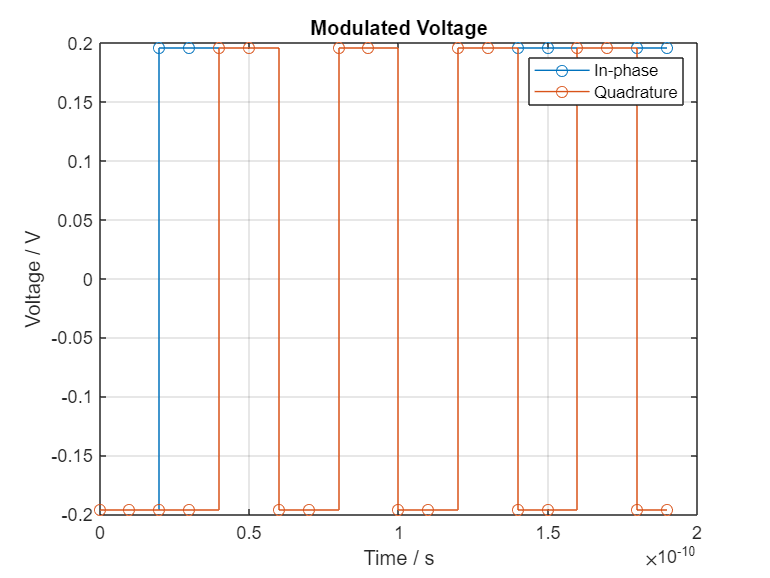


% Modulating voltage with generated symbols
vI_QPSK = ones(size(sourceSymbolsQPSK)); vQ_QPSK = zeros(size(sourceSymbolsQPSK));

vI_QPSK(real(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/16
vI_QPSK(real(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/16
vQ_QPSK(imag(sourceSymbolsQPSK)>0) = voltageLevels(2); % Maps 1 -> pi/16
vQ_QPSK(imag(sourceSymbolsQPSK)<0) = voltageLevels(1); % Maps -1 -pi/16

vI_QPSK_upsampled = repelem(vI_QPSK, SpS, 1); % Upsampling according to SpS
vQ_QPSK_upsampled = repelem(vQ_QPSK, SpS, 1); % Upsampling according to SpS

% Visualising in-phase and quadrature voltage
stairs(t(1:10*SpS), vI_QPSK_upsampled(1:10*SpS,1), "o-");
hold on
stairs(t(1:10*SpS), vQ_QPSK_upsampled(1:10*SpS,1), "o-");
title("Modulated Voltage")
xlabel("Time / s")
ylabel("Voltage / V")
legend("In-phase", "Quadrature")
grid on
hold off

### Pulse Shaping

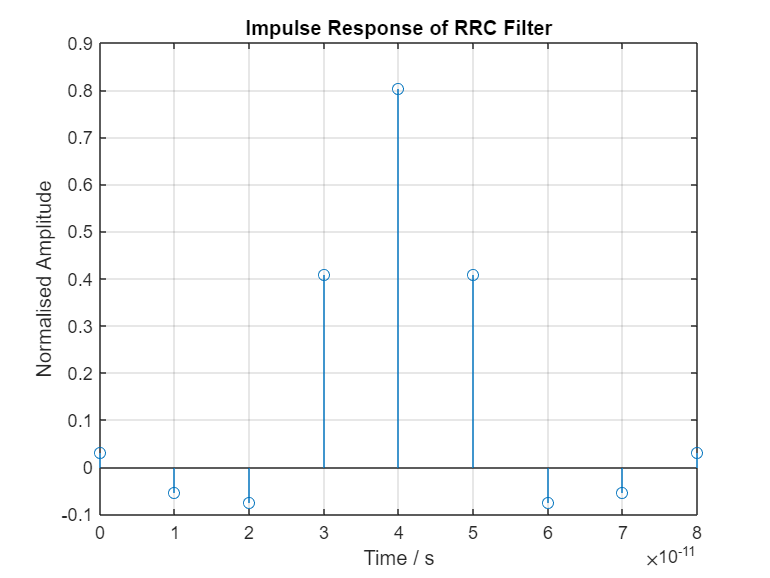

% RRC filter parameters
filterSpan = 4; % Span of RRC filter in no. of symbols
rollOff = 0.5;
filterResponse = rcosdesign(rollOff, filterSpan, SpS)';
samples = 1+(NSymb-1)*SpS + filterSpan*SpS;
v_shaped_t = [0:1:samples-1]*T;

% Visualisation of RRC filter
filterResponse_t = [0:1:filterSpan*SpS]*T; % time vector for the filter response
% filterResponse_t_interp = [0:0.25:filterSpan*SpS]*T;
% filterResponse_interp = interp1(filterResponse_t, filterResponse, filterResponse_t_interp, "spline");
% plot(filterResponse_t, filterResponse, "o", filterResponse_t_interp, filterResponse_interp, ":.");
stem(filterResponse_t, filterResponse, '-o');
title('Impulse Response of RRC Filter');
xlabel('Time / s');
ylabel('Normalised Amplitude');
grid on

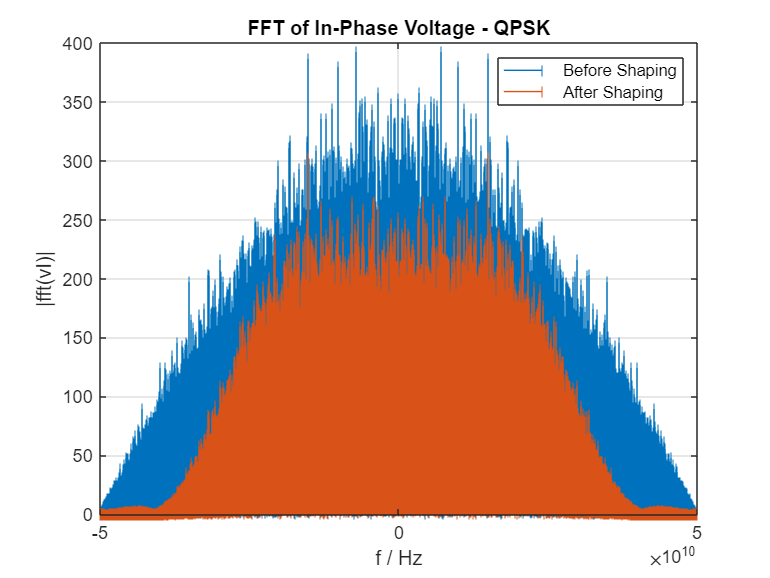


% ---------------------------------------------------------------------------

% FOR BPSK:
% Using RRC filter to shape vI and vQ
% Without AWGN
% vI_BPSK_shaped = upfirdn(vI_BPSK, filterResponse, SpS, 1); vQ_BPSK_shaped = upfirdn(vQ_BPSK, filterResponse, SpS, 1);
% With AWGN
% vI_BPSK_shaped_AWGN = upfirdn(real(v_BPSK_AWGN), filterResponse, SpS, 1); vQ_BPSK_shaped_AWGN = upfirdn(imag(v_BPSK_AWGN), filterResponse, SpS, 1);
% 
% % Frequency spectrum of voltage waveforms before and after filtering
% fft_vI_BPSK = fftshift(fft(real(vUpsampled_BPSK_AWGN(:,1)))); % FFT of noisy signal before shaping 
% freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);
% 
% fft_vI_BPSK_shaped = fftshift(fft(vI_BPSK_shaped_AWGN(:,1))); % FFT of noisy signal after shaping
% freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);
% 
% stem(freqArr, abs(fft_vI_BPSK), "|");
% hold on
% stem(freqArr_shaped, abs(fft_vI_BPSK_shaped), "|");
% title("FFT of In-Phase Voltage - BPSK");
% xlabel("f / Hz");
% ylabel("|fft(vI)|");
% legend("Before Shaping", "After Shaping")
% hold off
% grid on
% 
% % Visualising pulse-shaped voltages
% plot(v_shaped_t(1:10*SpS + filterSpan), vI_BPSK_shaped_AWGN(1:10*SpS + filterSpan,1), "o-");
% hold on
% plot(v_shaped_t(1:10*SpS + filterSpan), real(v_BPSK_AWGN(1:10*SpS + filterSpan,1)), "o-");
% title("Shaped In-Phase Voltage - BPSK");
% ylabel("Voltage / V");
% xlabel('Time / s');
% legend("Before shaping", "After Shaping");
% grid on
% hold off

% -------------------------------------------------------------------------

% FOR QPSK:
% Using RRC filter to shape vI and vQ
% Without AWGN
% vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);
% With AWGN
vI_QPSK_shaped = upfirdn(vI_QPSK, filterResponse, SpS, 1); vQ_QPSK_shaped = upfirdn(vQ_QPSK, filterResponse, SpS, 1);

% Frequency spectrum of voltage waveforms before filtering
fft_vI_QPSK = fftshift(fft(real(vI_QPSK_upsampled(:,1)))); % FFT of noisy signal before shaping
freqArr = [-NSymb*SpS/2:NSymb*SpS/2 - 1]/(T*NSymb*SpS);

fft_vI_QPSK_shaped = fftshift(fft(vI_QPSK_shaped(:,1))); % FFT of nosiy signal after shaping
freqArr_shaped = [-samples/2:samples/2 - 1]/(T*samples);

stem(freqArr, abs(fft_vI_QPSK), "|");
hold on
stem(freqArr_shaped, abs(fft_vI_QPSK_shaped), "|");
title("FFT of In-Phase Voltage - QPSK");
xlabel("f / Hz");
ylabel("|fft(vI)|");
legend("Before Shaping", "After Shaping");
hold off
grid on

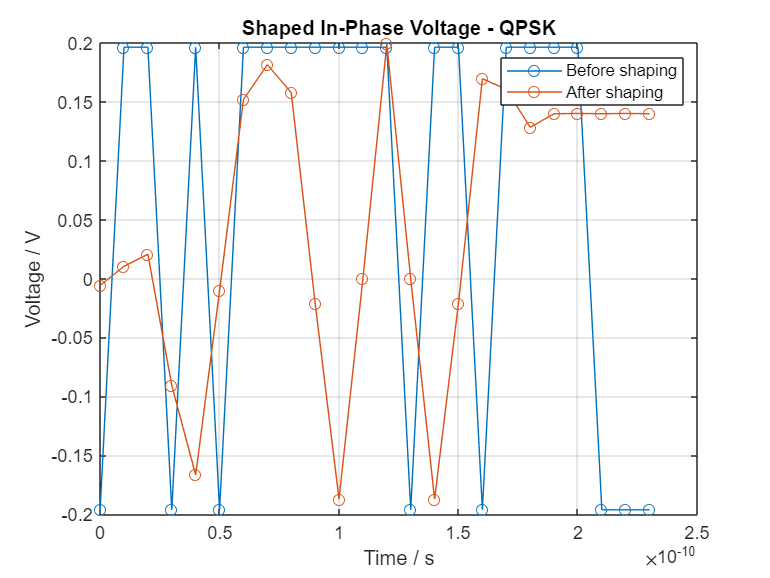


% Visualising pulse-shaped voltages
plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK(1:10*SpS + filterSpan,1), "o-");
hold on
plot(v_shaped_t(1:10*SpS + filterSpan), vI_QPSK_shaped(1:10*SpS + filterSpan,1), "o-");
title("Shaped In-Phase Voltage - QPSK");
ylabel("Voltage / V");
xlabel('Time / s');
legend("Before shaping", "After shaping");
grid on
hold off


bandwidth = 0.5*(1+rollOff)/T

bandwidth = 7.5000e+10

### IQ Modulation

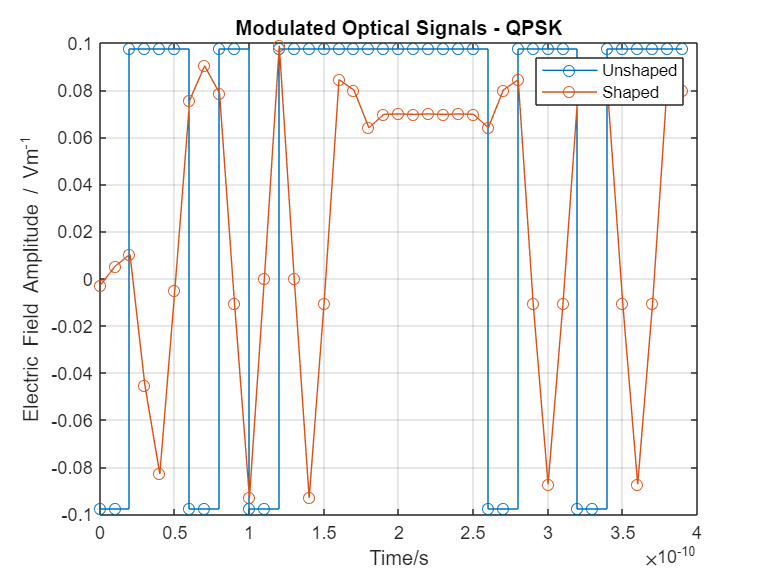

% Initialising laser parameters
lineWidth = 0;
laserPw_Lin = (1e-3)*10.^(laserPw_dBm/10);

% Modulating optical signals using IQM
Vpi = pi/2; % Voltge required to change phase of E-field by pi

for i=1:length(laserPw_dBm)
    % Generating output from laser modelled as a continuous-wave source
    laserE = Laser(laserPw_dBm(i), lineWidth, SpS, Rs, NSymb, 1); % Laser output to be used with unshaped signals
    laserE_shaped = Laser(laserPw_dBm(i), lineWidth, SpS, Rs, samples/SpS, 1); % Laser output to be used with shaped signals

    % For BPSK:
    % modOpticSigBPSK(:,:,i) = IQModulatorModified(real(vUpsampled_BPSK_AWGN), imag(vUpsampled_BPSK_AWGN), laserE, Vpi); % Unshaped
    % modOpticSigBPSK_shaped(:,:,i) = IQModulatorModified(vI_BPSK_shaped_AWGN, vQ_BPSK_shaped_AWGN, laserE_shaped, Vpi); % Shaped
    
    % For QPSK:
    modOpticSigQPSK(:,i) = IQModulatorModified(vI_QPSK_upsampled(:,i), vQ_QPSK_upsampled(:,i), laserE, Vpi); % Unshaped
    modOpticSigQPSK_shaped(:,i) = IQModulatorModified(vI_QPSK_shaped(:,i), vQ_QPSK_shaped(:,i), laserE_shaped, Vpi); % Shaped
end

% Test signals
% testBPSK = IQModulatorModified(vI_BPSK_upsampled, vQ_BPSK_upsampled, laserE, Vpi);
testQPSK = IQModulatorModified(vI_QPSK_upsampled, vQ_QPSK_upsampled, laserE, Vpi);

% Visualising modulated optical signals
% For BSPK:
% stairs(t(1:20*SpS), real(modOpticSigBPSK(1:20*SpS,1)), "o-");
% hold on
% plot(t(1:20*SpS), real(modOpticSigBPSK_shaped(1:20*SpS,1)), "o-");
% title("Modulated Optical Signals - BPSK")
% xlabel("Time/s")
% ylabel("Electric Field Amplitude / Vm^{-1}")
% legend("Unshaped", "Shaped")
% grid on
% hold off

% For QSPK:
stairs(t(1:20*SpS), real(modOpticSigQPSK(1:20*SpS,1)), "o-");
hold on
plot(t(1:20*SpS), real(modOpticSigQPSK_shaped(1:20*SpS,1)), "o-");
title("Modulated Optical Signals - QPSK")
xlabel("Time/s")
ylabel("Electric Field Amplitude / Vm^{-1}")
legend("Unshaped", "Shaped")
grid on
hold off

## Optical Channel

### Adding Attenuation, CD and/or Non-Linear Effects through the NLSE

fibreParams = struct("alpha", 0.2, "gamma", 1.3, "linkLength", 5, "D", 17); % Fibre parameters to be used in the SSF
stepSize = 1; % Step size for SSF method in km
CLambda = 1550e-9; % Central wavelength of optical carrier in m

% Solving the NLSE using the SSF method
for i=1:length(laserPw_dBm)
    % channelOutBPSK(:,i) = SplitStepFourier(modOpticSigBPSK(:,i), SpS, Rs, CLambda, fibreParams, stepSize); % BPSK unshaped
    channelOutQPSK(:,i) = SplitStepFourier(modOpticSigQPSK(:,i), SpS, Rs, CLambda, fibreParams, stepSize); % BPSK shaped
    % channelOutBPSK_shaped(:,i) = SplitStepFourier(modOpticSigBPSK_shaped(:,i), SpS, Rs, CLambda, fibreParams, stepSize); % QPSK unshaped
    channelOutQPSK_shaped(:,i) = SplitStepFourier(modOpticSigQPSK_shaped(:,i), SpS, Rs, CLambda, fibreParams, stepSize); % QPSK shaped
end

% Adding AWGN
for i=1:length(laserPw_dBm)
    for j=1:length(SNR_vals)
        channelOutQPSK_AWGN(:,i,j) = awgn(channelOutQPSK(:,i), convertSNR(SNR_vals(j),'ebno', samplespersymbol=1, bitspersymbol=2), 'measured'); % QPSK unshaped
        channelOutQPSK_shaped_AWGN(:,i,j) = awgn(channelOutQPSK_shaped(:,i), convertSNR(SNR_vals(j),'ebno', samplespersymbol=1, bitspersymbol=2), 'measured'); % QPSK shaped
    end
end

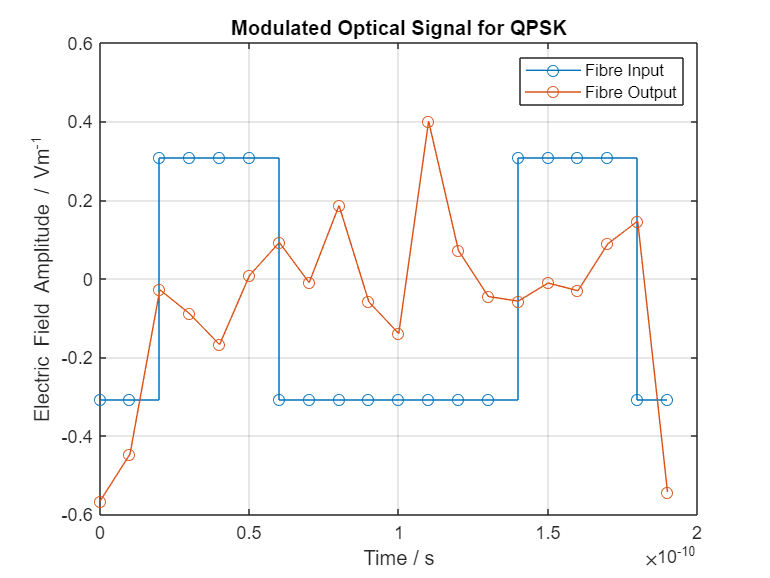

% Visualising optical signals before and after noise and attenuation
% BPSK without AWGN
% stairs(t(1:10*SpS), real(modOpticSigBPSK(1:10*SpS,11)), "-o"); 
% hold on
% plot(t(1:10*SpS), real(channelOutBPSK(1:10*SpS,11)), "-o");
% xlabel("Time / s"); 
% ylabel("Electric Field Amplitude / Vm^{-1}")
% title("Modulated Optical Signal for BPSK")
% legend("Fibre Input", "Fibre Output")
% grid on
% hold off
% 
% % BPSK with AWGN
% stairs(t(1:10*SpS), real(modOpticSigBPSK_AWGN(1:10*SpS,11)), "-o"); 
% hold on
% plot(t(1:10*SpS), real(channelOutBPSK_AWGN(1:10*SpS,11)), "-o");
% xlabel("Time / s"); 
% ylabel("Electric Field Amplitude / Vm^{-1}")
% title("Modulated Optical Signal for BPSK with AWGN")
% legend("Fibre Input", "Fibre Output")
% grid on
% hold off

% QPSK shaped
stairs(t(1:10*SpS), real(modOpticSigQPSK(1:10*SpS,11)), "-o"); 
hold on
plot(t(1:10*SpS), real(channelOutQPSK(1:10*SpS,11,1)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal for QPSK")
legend("Fibre Input", "Fibre Output")
grid on
hold off

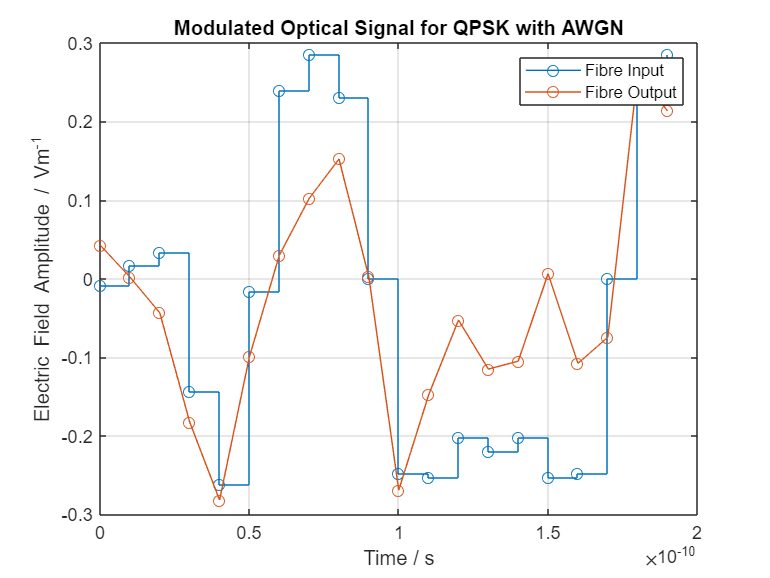


% QPSK unshaped
stairs(t(1:10*SpS), real(modOpticSigQPSK_shaped(1:10*SpS,11)), "-o"); 
hold on
plot(t(1:10*SpS), real(channelOutQPSK_shaped(1:10*SpS,11)), "-o");
xlabel("Time / s"); 
ylabel("Electric Field Amplitude / Vm^{-1}")
title("Modulated Optical Signal for QPSK with AWGN")
legend("Fibre Input", "Fibre Output")
grid on
hold off

## Receiver

### Optical Front-End

% Generating Local optical signal for coherent detection
Elo = laserE; % Identical to initial laser source
Elo_shaped = laserE_shaped; % Identical to initial laser source

% Generating output from optical front-end
eta_ph = 0.3; % Responsivity of photodetectors

% Computing output from optical front-end 
% Signals with AWGN + varying laser powers
for i=1:length(SNR_vals) 
    count = 1;
    for j=1:length(laserPw_dBm)
        % BPSK
        % OpticFEOutBPSK(:,count:count+1,i) = OpticalFrontEnd(channelOutBPSK(:,j,i), Elo, eta_ph, 1);
        % OpticFEOutBPSK_shaped(:,count:count+1,i) = OpticalFrontEnd(channelOutBPSK_shaped(:,j,i), Elo, eta_ph, 1);
        
        % QPSK
        OpticFEOutQPSK(:,count:count+1,i) = OpticalFrontEnd(channelOutQPSK_AWGN(:,j,i), Elo, eta_ph, 1);
        OpticFEOutQPSK_shaped(:,count:count+1,i) = OpticalFrontEnd(channelOutQPSK_shaped_AWGN(:,j,i), Elo_shaped, eta_ph, 1);
    
        count = count+2;
    end
end


% Test signals
count=1;
for i=1:length(laserPw_dBm)
    % Test signals with no added AWGN
    % testFEOutBPSK(:,count:count+1,i) = OpticalFrontEnd(testBPSK(:,i), Elo, eta_ph, 1);
    testFEOutQPSK(:,count:count+1) = OpticalFrontEnd(testQPSK(:,i), Elo, eta_ph, 1);
    count = count+2;
end

% TIA amplification and sampling using ADC
TIA_Gain = 1; % TIA amplification factor
Fs = SpS; % Sampling frequency of ADC

% Amplification and separation of in-phase and quadrature components
% BPSK
% OpticFEOutBPSK_I = TIA_Gain*OpticFEOutBPSK(1:SpS:end, 1:2:end); OpticFEOutBPSK_Q = TIA_Gain*OpticFEOutBPSK(1:SpS:end, 2:2:end); % Without AWGN
% OpticFEOutBPSK_shaped_I = TIA_Gain*OpticFEOutBPSK_shaped(:, 1:2:end); OpticFEOutBPSK_shaped_Q = TIA_Gain*OpticFEOutBPSK_shaped(:, 2:2:end); % With AWGN
% testFEOutBPSK_I = TIA_Gain*testFEOutBPSK(1:SpS:end, 1:2:end); testFEOutBPSK_Q = TIA_Gain*testFEOutBPSK(1:SpS:end, 2:2:end); % Test

% QPSK
OpticFEOutQPSK_I = TIA_Gain*OpticFEOutQPSK(:, 1:2:end, :); OpticFEOutQPSK_Q = TIA_Gain*OpticFEOutQPSK(:, 2:2:end, :); % Unshaped
OpticFEOutQPSK_shaped_I = TIA_Gain*OpticFEOutQPSK_shaped(:, 1:2:end, :); OpticFEOutQPSK_shaped_Q = TIA_Gain*OpticFEOutQPSK_shaped(:, 2:2:end, :); % Shaped
testFEOutQPSK_I = TIA_Gain*testFEOutQPSK(:, 1:2:end); testFEOutQPSK_Q = TIA_Gain*testFEOutQPSK(:, 2:2:end); % Test


## DSP

### Scaling

% Scaling factor between output of IQM and output of optical front-end
laserEMag = sqrt(laserPw_Lin);
% scaleFactor = sin(voltageLevels(2))*TIA_Gain*eta_ph*laserEMag.*laserEMag/2;
scaleFactor = 1;

% Cancelling the scaling factor:
% BPSK
% voltageI_BPSK = OpticFEOutBPSK_I./scaleFactor; voltageQ_BPSK = OpticFEOutBPSK_Q./scaleFactor; % Unshaped
% voltageI_BPSK_shaped = OpticFEOutBPSK_shaped_I./scaleFactor; voltageQ_BPSK_shaped = OpticFEOutBPSK_shaped_Q./scaleFactor; % Shaped
% testVI_BPSK = testFEOutBPSK_I./scaleFactor; testVQ_BPSK = testFEOutBPSK_Q./scaleFactor; % Test

% QPSK
voltageI_QPSK = OpticFEOutQPSK_I/scaleFactor; voltageQ_QPSK = OpticFEOutQPSK_Q/scaleFactor; % Unshaped
voltageI_QPSK_shaped = OpticFEOutQPSK_shaped_I/scaleFactor; voltageQ_QPSK_shaped = OpticFEOutQPSK_shaped_Q/scaleFactor; % Shaped
testVI_QPSK = testFEOutQPSK_I/scaleFactor; testVQ_QPSK = testFEOutQPSK_Q/scaleFactor; % Test

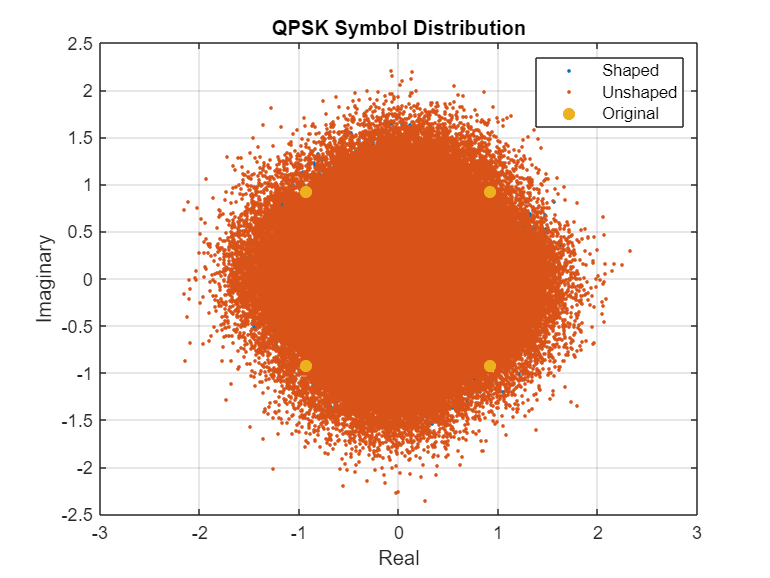

% Visualising symbol distributions
% BPSK
% plot(voltageI_BPSK_shaped(:,11)+1i*voltageQ_BPSK_shaped(:,11), "."); 
% hold on
% plot(testVI_BPSK(:,11), ".", MarkerSize=20);
% plot(voltageI_BPSK(:,11)+1i*voltageQ_BPSK(:,11), ".");
% xlabel("Real"); 
% ylabel("Imaginary")
% title("BPSK Symbol Distribution")
% legend("With AWGN", "Without AWGN", "Initial")
% grid on
% hold off

% QPSK
plot(voltageI_QPSK_shaped(:,11,1)+1i*voltageQ_QPSK_shaped(:,11,1), "."); 
hold on
plot(voltageI_QPSK(:,11,1)+1i*voltageQ_QPSK(:,11,1), ".");
plot(testVI_QPSK(:,11)+1i*testVQ_QPSK(:,11), ".", MarkerSize=20);
xlabel("Real"); 
ylabel("Imaginary")
title("QPSK Symbol Distribution")
legend("Shaped", "Unshaped", "Original")
grid on
hold off

## CD Compensation

% CD compensation
% c = 299792458; % Speed of light in m/s
% D = 17; % GVD is ps/nm/km
% linkLength = 50e3;
% N_CD = ceil(6.67*(D*1e-6)*(CLambda^2)*linkLength*(Rs^2)*SpS/(2*pi*c)); % CD Equalizer Length
% NFFT_BPSK = 2^9; NFFT_QPSK = 2^9;
% 
% for i=1:length(SNR_vals)
%     voltage_BPSK_CDC(:,i) = OverlapSaveCDC(voltageI_BPSK(:,i)+1i*voltageQ_BPSK(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_BPSK, N_CD);
%     voltage_QPSK_CDC(:,i) = OverlapSaveCDC(voltageI_QPSK(:,i)+1i*voltageQ_QPSK(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_QPSK, N_CD);
%     voltage_BPSK_AWGN_CDC(:,i) = OverlapSaveCDC(voltageI_BPSK_AWGN(:,i)+1i*voltageQ_BPSK_AWGN(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_BPSK, N_CD);
%     voltage_QPSK_AWGN_CDC(:,i) = OverlapSaveCDC(voltageI_QPSK_AWGN(:,i)+1i*voltageQ_QPSK_AWGN(:,i), D, linkLength, CLambda, Rs, 1, SpS, NFFT_QPSK, N_CD);
% end

### Filtering and Downsampling

% Downsampling signals after CDC
% BPSK
% voltageI_BPSK_CDC = real(voltage_BPSK_CDC(1:SpS:end, :)); voltageQ_BPSK_CDC = imag(voltage_BPSK_CDC(1:SpS:end, :)); % Unshaped
% voltageI_BPSK_shaped_CDC = real(voltage_BPSK_shaped_CDC(1:SpS:end, :)); voltageQ_BPSK_shaped_CDC = imag(voltage_BPSK_shaped_CDC(1:SpS:end, :)); % Shaped
% QPSK
% voltageI_QPSK_CDC = real(voltage_QPSK_CDC(1:SpS:end, :)); voltageQ_QPSK_CDC = imag(voltage_QPSK_CDC(1:SpS:end, :)) % Unshaped
% voltageI_QPSK_shaped_CDC = real(voltage_QPSK_shaped_CDC(1:SpS:end, :)); voltageQ_QPSK_shaped_CDC = imag(voltage_QPSK_shaped_CDC(1:SpS:end, :)); % Shaped

% Downsampling signals without CDC
% BPSK
% voltageI_BPSK = voltageI_BPSK(1:SpS:end, :); voltageQ_BPSK = voltageQ_BPSK(1:SpS:end, :); % Unshaped
% voltageI_BPSK_shaped = voltageI_BPSK_shaped(1:SpS:end, :); voltageQ_BPSK_shaped = voltageQ_BPSK_shaped(1:SpS:end, :); % Shaped
% QPSK
voltageI_QPSK = voltageI_QPSK(1:SpS:end, :, :); voltageQ_QPSK = voltageQ_QPSK(1:SpS:end, :, :); % Unshaped
testVI_QPSK = testVI_QPSK(1:SpS:end, :); testVQ_QPSK = testVQ_QPSK(1:SpS:end, :); 


% Matched filtering shaped signals
for i=1:length(SNR_vals)
    voltageI_QPSK_shaped_filtered(:,:,i) = upfirdn(voltageI_QPSK_shaped(:,:,i), filterResponse, 1, SpS); 
    voltageQ_QPSK_shaped_filtered(:,:,i) = upfirdn(voltageQ_QPSK_shaped(:,:,i), filterResponse, 1, SpS); 
end

voltageI_QPSK_shaped = voltageI_QPSK_shaped_filtered(filterSpan+1 : end-filterSpan,:,:); 
voltageQ_QPSK_shaped = voltageQ_QPSK_shaped_filtered(filterSpan+1 : end-filterSpan,:,:);

### Decoding, Decision and Evaluating BER

% Decoding recieved symbols

% BPSK
% Test voltages
% testSymbolsBPSK = testVI_BPSK + 1i*testVQ_BPSK;
% testIntsBPSK = pskdemod(testSymbolsBPSK, 2);
% testBitsBPSK = int2bit(testIntsBPSK, 1);
% biterr(testBitsBPSK, sourceBitsBPSK)

% Unshaped
% decodedSymbolsBPSK = voltageI_BPSK + 1i*voltageQ_BPSK; 
% decodedIntsBPSK = pskdemod(decodedSymbolsBPSK, 2);
% decodedBitsBPSK = int2bit(decodedIntsBPSK, 1);

% Shaped
% decodedSymbolsBPSK_shaped = voltageI_BPSK_shaped + 1i*voltageQ_BPSK_shaped; 
% decodedIntsBPSK_shaped = pskdemod(decodedSymbolsBPSK_shaped, 2);
% decodedBitsBPSK_shaped = int2bit(decodedIntsBPSK_shaped, 1);

% --------------------------------------------------------------------------------------------

% QPSK
%Test Votlages
testSymbolsQPSK = testVI_QPSK + 1i*testVQ_QPSK;
testIntsQPSK = pskdemod(testSymbolsQPSK, 4, pi/4);
testBitsQPSK = int2bit(testIntsQPSK, 2);
biterr(testBitsQPSK, sourceBitsQPSK)

ans = 0


% Unshaped
decodedSymbolsQPSK = voltageI_QPSK + 1i*voltageQ_QPSK;
for i=1:length(SNR_vals)
    decodedIntsQPSK = pskdemod(decodedSymbolsQPSK(:,:,i), 4, pi/4);
    decodedBitsQPSK = int2bit(decodedIntsQPSK, 2);
    for j=1:length(laserPw_dBm)
        [~, BER_QPSK(i,j)] = biterr(decodedBitsQPSK(:,j), sourceBitsQPSK(:,j));
    end
end

% Shaped
decodedSymbolsQPSK_shaped = voltageI_QPSK_shaped + 1i*voltageQ_QPSK_shaped; 
for i=1:length(SNR_vals)
    decodedIntsQPSK_shaped = pskdemod(decodedSymbolsQPSK_shaped(:,:,i), 4, pi/4);
    decodedBitsQPSK_shaped = int2bit(decodedIntsQPSK_shaped, 2);
    for j=1:length(laserPw_dBm)
        [~, BER_QPSK_shaped(i,j)] = biterr(decodedBitsQPSK_shaped(:,j), sourceBitsQPSK(:,j));
    end
end

### BER Plots

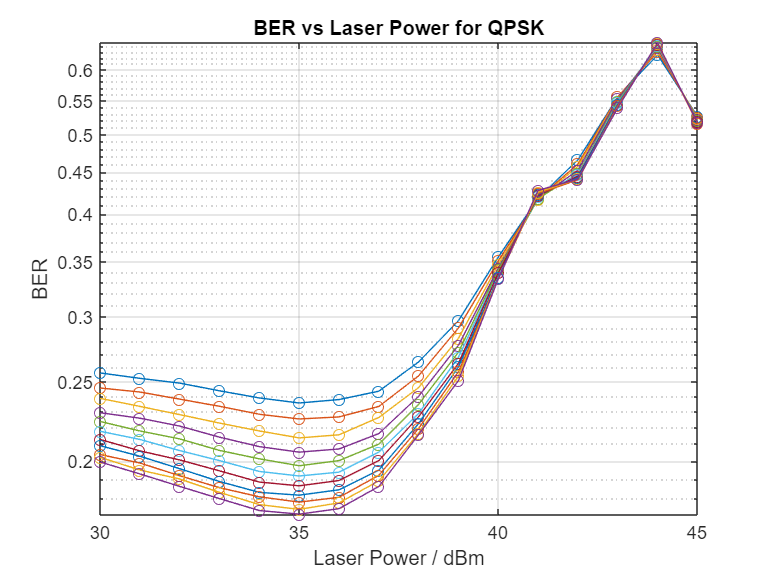

% Visualising variation of BER with different input laser powers and AWGN

% QPSK
semilogy(laserPw_dBm, BER_QPSK', "-o"); % Unshaped
title("BER vs Laser Power for QPSK")
xlabel("Laser Power / dBm")
ylabel("BER")
grid on

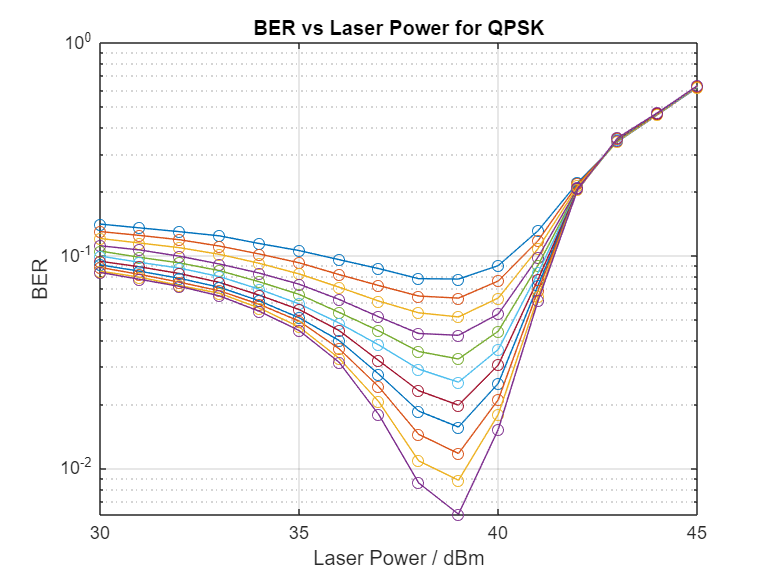


semilogy(laserPw_dBm, BER_QPSK_shaped', "-o"); % Unshaped
title("BER vs Laser Power for QPSK")
xlabel("Laser Power / dBm")
ylabel("BER")
grid on
hold off


% semilogy(SNR_vals(1:11), 0.5*erfc(sqrt(10.^(SNR_vals(1:11)/10))));
% hold on
% semilogy(SNR_vals(1:11), BER_QPSK(1:11), "-o");
% title("BER vs SNR for QPSK")
% xlabel("SNR / dB")
% ylabel("BER")
% legend("Theoretical Min", "Simulation")
% grid on
% hold off